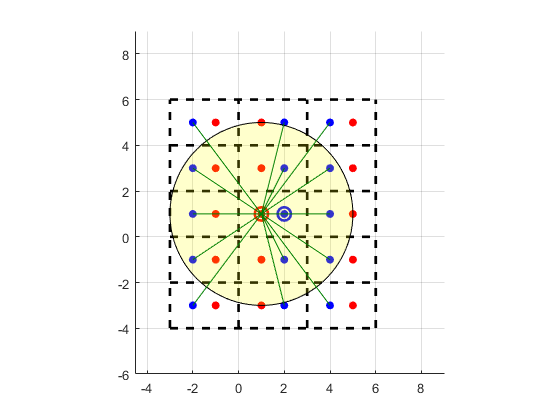

clear
TEST = 1;

switch TEST
	case 1
		dim = [3 2];		%	[width height]	(1 - 1250)
		pos0 = [1 1];		%	[x y]			(1 - (width,height-1))
		pos1 = [2 1];		%	[x y]			(1 - (width,height-1))
		max_dist = 4;

	case 2
		dim = [300 275];		%	[width height]	(1 - 1250)
		pos0 = [150 150];		%	[x y]			(1 - (width,height-1))
		pos1 = [185 100];		%	[x y]			(1 - (width,height-1))
		max_dist = 500;
end
PlotData(dim, pos0, pos1, max_dist);

N = SearchQuadrant(dim, pos0, pos1, max_dist) ...
	+ SearchQuadrant(dim, [dim(1)-pos0(1) pos0(2)], [dim(1)-pos1(1) pos1(2)], max_dist) ...
	+ SearchQuadrant(dim, [pos0(1) dim(2)-pos0(2)], [pos1(1) dim(2)-pos1(2)], max_dist) ...
	+ SearchQuadrant(dim, [dim(1)-pos0(1) dim(2)-pos0(2)], [dim(1)-pos1(1) dim(2)-pos1(2)], max_dist);

%	Are x-positions half-way between
% if (dim(1)==2*pos0(1)) && (dim(1)==2*pos1(1))
% 	N = 2*N;
% else
% 	N = N + SearchQuadrant(dim, [dim(1)-pos0(1) pos0(2)], [dim(1)-pos1(1) pos1(2)], max_dist);
% end
% 
% if (dim(2)==2*pos0(2)) && (dim(2)==2*pos1(2))
% 	N = 2*N;
% else
% 	N = N ...
% 		+ SearchQuadrant(dim, [pos0(1) dim(2)-pos0(2)], [pos1(1) dim(2)-pos1(2)], max_dist) ...
% 		+ SearchQuadrant(dim, [dim(1)-pos0(1) dim(2)-pos0(2)], [dim(1)-pos1(1) dim(2)-pos1(2)], max_dist);
% end
% N + 1

function N = SearchQuadrant(dim, pos0, pos1, max_dist, dir)
%	Find maximum replication index
nmax = ceil(.5*(max_dist + pos0)./dim);

p0 = pos0;
p1 = pos1;
if dir(1)<0
	p0(1) = dim(1)-p0(1);
	p1(1) = dim(1)-p1(1);
end
if dir(2)<0
	p0(2) = dim(2)-p0(2);
	p1(2) = dim(2)-p1(2);
end
[X0, Y0] = GetPositions(nmax, dim, p0, pos0, max_dist);
[X1, Y1] = GetPositions(nmax, dim, p1, pos0, max_dist);

%	Get distances
dX0 = (X0-pos0(1));
dY0 = (Y0-pos0(2));
dX1 = (X1-pos0(1));
dY1 = (Y1-pos0(2));
d20 = dX0.^2 + dY0.^2;
d21 = dX1.^2 + dY1.^2;

%	Find same angles
ind = Column(~any((dY0.*Row(dX1))==(Row(dY1).*dX0) & (d20<=Row(d21)), 1)) ...
	& (d21<=max_dist^2);

N = length(unique(dY1(ind)./dX1(ind)));
end

function [x, y] = GetPositions(nmax, dim, pos, pos0, max_dist)
x = [pos(1); Column(2*(1:nmax(1))*dim(1) + [-1; 1].*pos(1))];
y = [pos(2); Column(2*(1:nmax(2))*dim(2) + [-1; 1].*pos(2))];

[x, y] = meshgrid(Row(x(x<=max_dist+pos0(1))), Column(y(y<=max_dist+pos(2))));
x = Column(x);
y = Column(y);
% x = Column(x(2:end));
% y = Column(y(2:end));
end


## Get Replicated

## ind Overlaps

% 
% %	Get tan(theta)
% th0 = dY0./dX0;
% th1 = dY1./dX1;
% 
% % ind1 = (th0==Row(th1))
% ind1 = dY0.*Row(dX1)==Row(dX0).*dY1
% ind2 = (d20<=Row(d21))
% ind1 & ind2
% ind = ~any(ind1 & ind2, 1) & Row(d21<=max_dist^2);
% [~any(ind1 & ind2, 1);
% 	Row(d21<=max_dist^2);
% 	ind]
% th1.'
% th1(ind).'
% unique(th1(ind)).'
% N = length(unique(th1(ind)))

## Plot Results

function PlotData(dim, pos0, pos1, max_dist)
width = dim(1);
height = dim(2);
x0 = pos0(1);
y0 = pos0(2);
x1 = pos1(1);
y1 = pos1(2);
 
nmax = ceil((max_dist + pos0)./(2*dim));

%	Index locations
nx = (-nmax(1):nmax(1)).';
ny = (-nmax(2):nmax(2)).';

%	My positions
X0 = Column(2*nx*width + [1 -1]*x0);
Y0 = Column(2*ny*height + [1 -1]*y0);

%	Trainer positions
X1 = Column(2*nx*width + [1 -1]*x1);
Y1 = Column(2*ny*height + [1 -1]*y1);

indx = (abs(X0-x0)<=max_dist) & (abs(X1-x0)<=max_dist);
indy = (abs(Y0-y0)<=max_dist) & (abs(Y1-y0)<=max_dist);
X0 = X0(indx);
X1 = X1(indx);
Y0 = Y0(indy);
Y1 = Y1(indy);

%	Create full co-ordinates
[X0, Y0] = meshgrid(X0.', Y0);
X0 = Column(X0);
Y0 = Column(Y0);

[X1, Y1] = meshgrid(X1.', Y1);
X1 = Column(X1);
Y1 = Column(Y1);

fig = gcf;
clf(fig);
ax = axes(fig);

%	Plot rooms
xmin = min(min(X0), min(X1));
xmax = max(max(X0), max(X1));
ymin = min(min(Y0), min(Y1));
ymax = min(max(Y0), max(Y1));
nxmin = floor(xmin/width);
nxmax = ceil(xmax/width);
nymin = floor(ymin/height);
nymax = ceil(ymax/height);

line(repmat(width*[nxmin; nxmax], [1 nymax-nymin+1]), [1; 1].*(nymin:nymax)*height, ...
	"LineStyle", "--", "Color", "k", "LineWidth", 2);
line([1; 1].*(nxmin:nxmax)*width, repmat(height*[nymin; nymax], [1 nxmax-nxmin+1]), ...
	"LineStyle", "--", "Color", "k", "LineWidth", 2);

%	Replicated my positions
line(X0, Y0, ...
	"Color", "None", "MarkerFaceColor", "r", "Marker", "o");

%	Replicated trainer positions
line(X1, Y1, ...
	"Color", "None", "MarkerFaceColor", "b", "Marker", "o");

%	My position
line(pos0(1), pos0(2), "Color", "r", "Marker", "o", "MarkerSize", 10, "LineWidth", 2);

%	Trainer position
line(pos1(1), pos1(2), "Color", "b", "Marker", "o", "MarkerSize", 10, "LineWidth", 2);

%	Max distance
th = linspace(0, 2*pi, 100).';
patch(x0+max_dist*cos(th), x0+max_dist*sin(th), "y", "FaceAlpha", .2);

%	Plot all directions
line(x0+[0; 1].*Row(X1-x0), y0+[0; 1].*Row(Y1-y0), ...
	"Color", [0 .5 0]);

grid on;
axis equal;
xlim(1.5*width*[nxmin nxmax]);
ylim(1.5*height*[nymin nymax]);
end

function x = Column(x) 
x = x(:);
end

function x = Row(x) 
x = reshape(x, 1, []);
end

function x = Plane(x) 
x = reshape(x, 1, 1, []);
end
